# Beam tracking in CDL Channels

## Introduction

    In this project, I simulated and compared fixed beam forming and beam tracking in the 5g mmWave setting. In my initial set up, I simulate a link at 28 GHz with a 4 by 4 URA transmiter and a single antenna receiver, using the 3GPP CDL-C channel.

**Why did I choose the 3GPP CDL-C channel?**

- I chose the 3GPP CDL-C because it can be used for simulated testing of 5G systems like an enviroment you might find in a busy city

**Fixed beam forming vs. beam tracking, what's the difference**

- One one hand, we have beam tracking which adapts and selects the best beam based on the users direction

- On the other hand, fixed beam forming sticks with a predetermined direction

**In this implemantation,**

I tested how tracking is superior in establishing signal quality (SNR) and evaluated the pointing accuracy under movement. These changes were presented as random "jitters" to simulate progressively changing angles

- Although jitters are often thought of as [*"the variation in time delay between when a signal is transmitted and when it's received over a network connection"*](https://www.ir.com/guides/what-is-network-jitter) (reference 1), in this case I am simulating jitters as random changes in the user's azimuth/elevation angles

Among other things, this notebook includes: channel setup, setting up the beam directions, simulating time slots, sweeping SNR's, plot evaluations, and delay tracking.

## CDL Channel and Antenna Initial setup

- *To reiterate: *In my initial set up, I simulate a link at 28 GHz with a 4 by 4 URA transmiter and a single antenna receiver, using the 3GPP CDL-C channel.

- tap delay profile is plotted to visualize the power across different delays

% project by Cesar Sanchez, 2025

%initial setup
clear;
clc;

rng(23) 

fc = 28e9;
c = physconst('LightSpeed');
lambda = c / fc;

%fprintf('fc = %.2f GHz\n', fc / 1e9)


fprintf('wavelength = %.2f mm\n', lambda * 1e3) 

wavelength = 10.71 mm


%channel setup
myChan = nrCDLChannel;
myChan.DelayProfile = 'CDL-C';
myChan.CarrierFrequency = fc;


myChan.DelaySpread = 60e-9;
myChan.MaximumDopplerShift = 50;


% tx array
txArr = phased.URA([4 4], lambda/2);


%rxArr = phased.URA([1 1], lambda/2);


rxArr = phased.ConformalArray( ...
   'Element', phased.IsotropicAntennaElement, ...
   'ElementPosition', [0; 0; 0]);


myChan.TransmitAntennaArray = txArr;
myChan.ReceiveAntennaArray = rxArr;


fprintf('tx elems: %d\n', prod(txArr.Size))

tx elems: 16



fprintf('rx elems: %d\n', getNumElements(rxArr))

rx elems: 1




%fprintf('ant spacing: %.2f\n', lambda/2)


% pull delay power info
infoCDL = info(myChan);


%tapDelays = infoCDL.PathDelays * 1e9;
%tapGains = 10 * log10(infoCDL.AveragePathGains); 


tapDelays = infoCDL.PathDelays * 1e9;
tapGains = infoCDL.AveragePathGains;   % already in dB

fprintf('num taps = %d\n', length(tapDelays))

num taps = 24


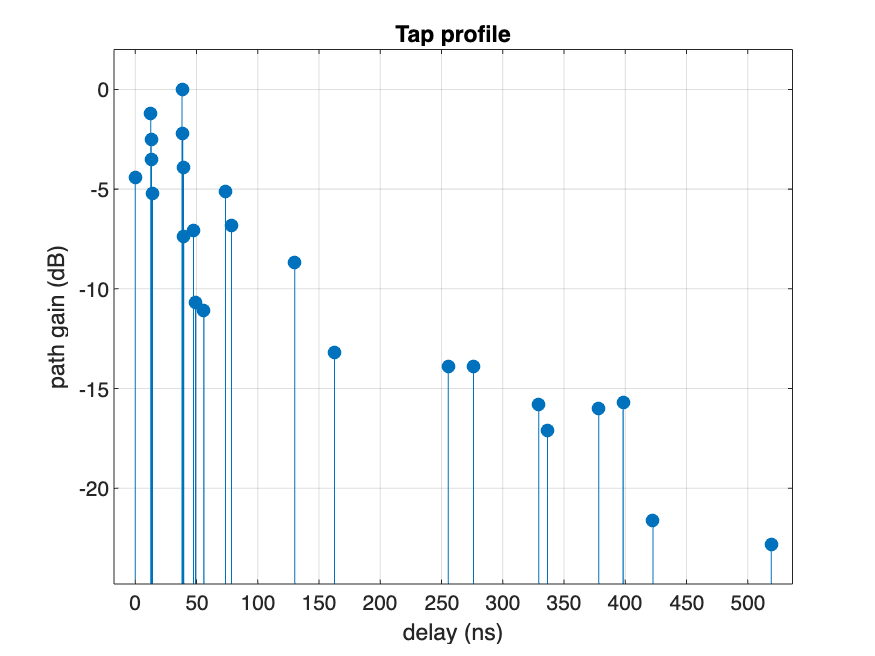


%disp(tapDelays)


% plot

%figure

%stem(tapDelays, tapGains, 'filled')  % waarning okay
%xlabel('delay (ns)')

%ylabel('path gain (dB)')
%title('tap profile')
%grid on


% plotting
figure      % this figure, stem orientations is upwards 
stem(tapDelays, tapGains, 'filled', 'BaseValue', min(tapGains)-2);

ylim([min(tapGains)-2, 2]);            % spacing, 0

xlabel('delay (ns)'); 

ylabel('path gain (dB)');
title('Tap profile'); 
grid on

## Beam Generation / Tracker

To simulate signals in different directions, I created a collection of beams with each beam pointing at a particular angle on a grid of azimuth and elevation values. 

- Essentially each direction is formed as a vector. For the tracking aspect, I simulate how a transmitter would follow a user in motion. 

- At every time slot, I compare the users current direction to my beam collection and pick the beam pointing closest to them. 

- I based the the "closeness" by how well the beams align (determined using the dot product)

% building the beam vecs and tracking form

% angle search grid
azSet = -60:15:60;
elSet = -30:15:30;


[azGrid, elGrid] = meshgrid(azSet, elSet);
numDirs = numel(azGrid);


fprintf('generating %d beams...\n', numDirs)

generating 45 beams...



% steering
steerVec = phased.SteeringVector( ...
   'SensorArray', txArr, ...
   'IncludeElementResponse', true );


% hold beamformers
beamVecs = zeros(prod(txArr.Size), numDirs);


for i = 1:numDirs
   az = azGrid(i);
   el = elGrid(i);
   vec = steerVec(fc, [az; el]);
   beamVecs(:, i) = vec;


   %fprintf('%d az=%d el=%d\n', i, az, el)  
end


%fprintf('shape = [%d x %d]\n', size(beamVecs,1), size(beamVecs,2))


testAngle = [0; 0];
vecTest = steerVec(fc, testAngle);


idxTest = findClosestVec(beamVecs, vecTest);


%fprintf('closest match for [0 0] is beam num #%d\n', idxTest)


function idx = findClosestVec(allVecs, targetVec)
   targetVec = targetVec/norm(targetVec);
   vecsT = allVecs';  
   %fprintf('size of vect = [%d x %d]\n', size(vecsT,1), size(vecsT,2));


   projVals = abs(vecsT * targetVec);
   %[~, idx] = max(real(...))  
   [~, idx] = max(projVals);   % best match
end

## Slot based Tracking simulation

Here I simulate 120 time slots, where the users angle of departure, or AoD, is randonly chaged essentially mimicking small movements over time.

At every slot, I measured the SNR using two setups

- one where a fixed beam never changes

- one with a tracking beam that updates direction to follow the user

% simulating beam tracking

nSlots = 120;
slotDur = 1e-3;

%azJit = 1.5;
%elJit = 0.8;
azJit = 3.0;
elJit = 2.0;

startSlot = 0;


azPath = zeros(1, nSlots);
elPath = zeros(1, nSlots);


vec0 = steerVec(fc, [0; 0]);   % center dir


fixedIdx = findClosestVec(beamVecs, vec0);
fixedVec = beamVecs(:, fixedIdx);

fprintf('fixed beam idx = %d\n', fixedIdx)

fixed beam idx = 23



snrFixed = zeros(1, nSlots);
snrTracked = zeros(1, nSlots);


for i = 1:nSlots
   % move the aod a bit
   if i > 1
       azPath(i) = azPath(i-1) + randn()*azJit;
       elPath(i) = elPath(i-1) + randn()*elJit;
   end


   % aod this slot
   aod = [azPath(i); elPath(i)];
   %aod = [azPath(i); 0];  


   vTrue = steerVec(fc, aod);


   % find beaM
   trackIdx = findClosestVec(beamVecs, vTrue);
   %trackIdx = fixedIdx;  
   trackVec = beamVecs(:, trackIdx);


   % gain = dot product mag
   gFixed = abs(fixedVec' * vTrue)^2;
   gTrack = abs(trackVec' * vTrue)^2;


   %gTrack = real(trackVec' * vTrue)^2;  


   % snr
   snrFixed(i) = 10 * log10(gFixed / 0.1);
   snrTracked(i) = 10 * log10(gTrack / 0.1);


   %snrTracked(i) = 10 * log10(gTrack); 


   %fprintf('slot %d fixed = %.2f, tracked = %.2f\n', i, snrFixed(i), snrTracked(i))
end


fprintf('done simulating %d slots\n', nSlots)

done simulating 120 slots


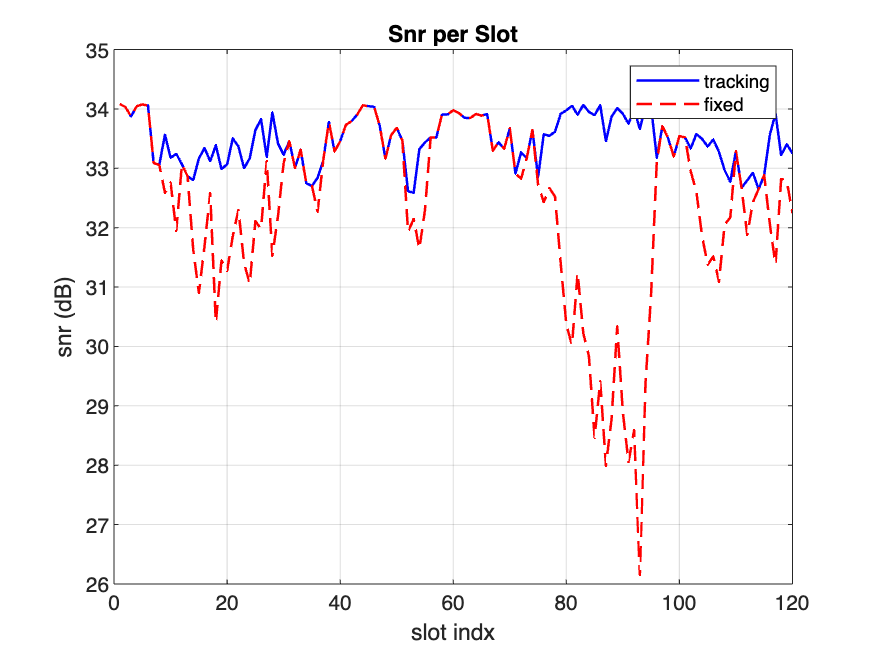


figure

%plot(1:nSlots, snrFixed, 'r--', 'LineWidth', 1.2); hold on;
%plot(1:nSlots, snrTracked, 'b-', 'LineWidth', 1.2);

plot(1:nSlots, snrTracked, 'b-', 'LineWidth', 1.2); hold on
plot(1:nSlots, snrFixed,   'r--', 'LineWidth', 1.2);
%plot(1:nSlots, snrFixed,   'm--', 'LineWidth', 1.2);

xlabel('slot indx')
ylabel('snr (dB)')

legend('tracking', 'fixed')
title('Snr per Slot')
grid on

Plot analysis: In the SNR per Slot plot, we see how the SNR changes across 120 slots for tracking and fixed beam respectively. 

- We can see that early on performance is pretty comparable for both, however, we see that as time goes on the user's aod has progressively been pushed away from center 

- It is around slot 75-80 we see a dramatic difference start which can be attributed to loss allignment in the fixed beam

- On the other hand, the tracking beam manages to maintain a steady SNR throughout which can be attributed to the updated directions it maintains in following the user

Although this conclusion may have been intuitively obvious to some readers, we highlight how crticial tracking can be in maintaining signal quality. 

- In earlier runs I used smaller jitter values for both the fixed and tracking beams. These smaller jitter values performed pretty similarly which made the difference hard to see graphically (too much line overlapping)

- To better visualize how tracking helps under movement, I increased the jitter values from (azimuth: 1.5, elevation: 0.8) to (azimuth: 3.0, elevation: 2.0)

## SNR Sweep and Error Evaluation

In setting up my SNR Sweep and Error Evaluation, I sough out to test how both beam strategies preform under different noise levels

To do this I:

- ran a sweep from 0dB to 30dB input SNR in steps of 5

- Simulated 120 time slots and calculated the average output SNR and tracked pointing error

%% trying snr sweep and comparatives tracking


snrVals = 0:5:30;
nSNRs = length(snrVals);
nSlots = 120;


snrOut_fixed = zeros(1, nSNRs);
snrOut_track = zeros(1, nSNRs);
errList = zeros(1, nSNRs);


[azMesh, elMesh] = meshgrid(azSet, elSet);


snrCheck = [];   
checkGain = 0;     % low snr tracker


for s = 1:nSNRs

   snrDB = snrVals(s);
   snrLin = 10^(snrDB/10);


   noisePwr = 1/snrLin;


   azPath = zeros(1, nSlots);
   elPath = zeros(1, nSlots);


   tmpFix = zeros(1, nSlots);
   tmpTrack = zeros(1, nSlots);
   tmpErr = zeros(1, nSlots);


   currTmpErr = zeros(1, nSlots);
    


   for i = 1:nSlots
       if i> 1
           azPath(i) = azPath(i-1) + randn()*azJit;
           elPath(i) = elPath(i-1) + randn()*elJit;
       end


       aod = [azPath(i); elPath(i)];


       %aod = [azPath(i); 0];     
       %aod = [0; elPath(i)];      

       %aod = aod + randn(2,1)*0.5;


       vTrue = steerVec(fc, aod);


       idxTrack = findClosestVec(beamVecs, vTrue);
       trackVec = beamVecs(:, idxTrack);


       g1 = abs(fixedVec' * vTrue)^2;
       g2 = abs(trackVec' * vTrue)^2;


       tmpFix(i) = 10 * log10(g1 / noisePwr);
       tmpTrack(i) = 10 * log10(g2 / noisePwr);


       %tmpTrack(i) = 10 * log10(g2);  
       %tmpFix(i) = 10 * log10(g1);    


       estAz = azMesh(idxTrack);
       estEl = elMesh(idxTrack);
       tmpErr(i) = sqrt((aod(1)-estAz)^2 + (aod(2)-estEl)^2);


       %%%%% testing, not necessary for final execution %%%%


       %if mod(i, 25) == 0
       %    fprintf('s%d slot%d  g=%.2f  snr=%.1f\n', s, i, g2, tmpTrack(i));
       %end


     
       %if s == 1 && i <= 3
       %    fprintf('  aod: [%.1f %.1f]  est: [%.1f %.1f]\n', ...
       %        aod(1), aod(2), estAz, estEl);
       %end


       if g2 < 0.01
           checkGain = g2;
           %fprintf('   low beamform gain slot %d\n', i);
       end
   end


   snrOut_fixed(s) = mean(tmpFix);
   snrOut_track(s) = mean(tmpTrack);
   errList(s) = mean(tmpErr);


   fprintf('snr %2d dB  avg=%.2f  err=%.1f\n', ...
       snrDB, snrOut_track(s), errList(s));
end

snr  0 dB  avg=23.55  err=6.7
snr  5 dB  avg=28.34  err=8.0
snr 10 dB  avg=33.56  err=5.4
snr 15 dB  avg=38.56  err=5.3
snr 20 dB  avg=43.54  err=5.4
snr 25 dB  avg=48.63  err=5.3
snr 30 dB  avg=53.46  err=5.9


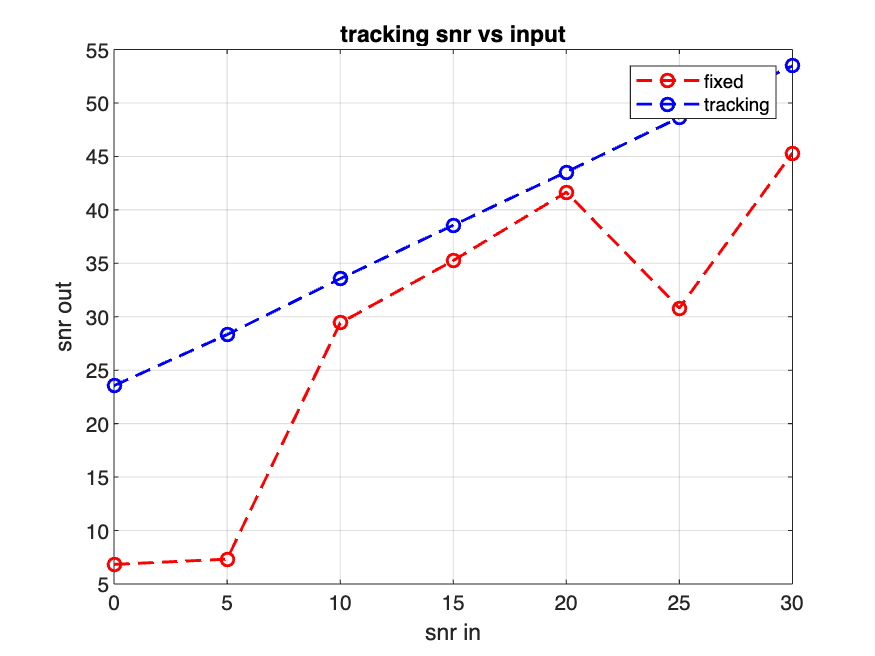


% plot snr
figure


plot(snrVals, snrOut_fixed, 'r--o', 'LineWidth', 1.4); hold on
plot(snrVals, snrOut_track, 'b--o', 'LineWidth', 1.4);
%plot(snrVals, snrOut_track, 'b-o', 'LineWidth', 1.4);


xlabel('snr in')
ylabel('snr out')

title('tracking snr vs input')

legend('fixed', 'tracking')

grid on

Plot Analysis:

As expected, tracking outperforms fixed beam across the SNR range meaning that it maintains higher signal quality

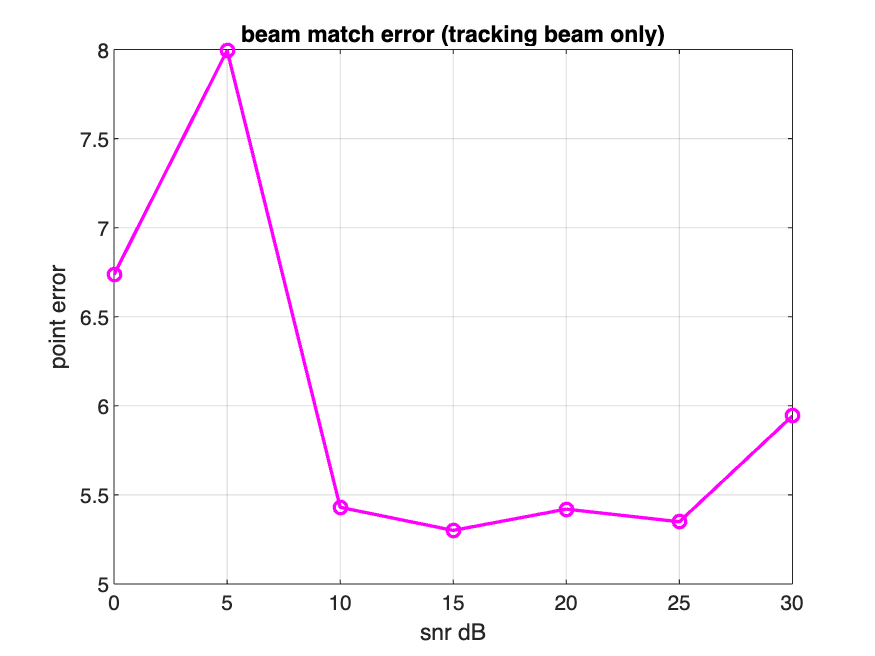

% plot err
figure


%plot(snrVals, errList, 'k-o', 'LineWidth', 1.4);
plot(snrVals, errList, 'm-o', 'LineWidth', 1.6);


xlabel('snr dB')
ylabel('point error')


title('beam match error (tracking beam only)')
grid on

Plot analysis: 

- This plot shows that the tracking beam maintains a generally low directional error

- Overall, the tracker performs well under simulated circumstances

- NOTE: this is only for the beam tracking, fixed does not have a plot

% final eval


fprintf('results for each snr setting:\n\n')

results for each snr setting:




fprintf(' snr   fixed out    tracked out   avg err of tracker (deg)\n')

 snr   fixed out    tracked out   avg err of tracker (deg)




for i = 1:length(snrVals)
   fprintf(' %2d     %8.4f       %8.4f        %6.2f\n', ...
       snrVals(i), snrOut_fixed(i), snrOut_track(i), errList(i));
end

  0       6.8300        23.5533          6.74
  5       7.3211        28.3359          8.00
 10      29.4162        33.5584          5.43
 15      35.2557        38.5592          5.30
 20      41.6502        43.5419          5.42
 25      30.8154        48.6321          5.35
 30      45.3191        53.4623          5.94


### Results analysis:

The results show that the tracking beam outperforms the fixed beam across all metrics. Most notably, the fixed beam underperforms at low SNRs where the tracking excels.

## **Conclusion**

**This project showed that the beam tracking method is overall a superior method compared to fixed beam. **This conclusion may have seemed obvious to some, but this thorough examination help us visualize exactly how important it can be which underscores the importance of tracking in wireless environments.

Useful References:

- https://www.ir.com/guides/what-is-network-jitter

- Wireless Communications, Unit09_MIMO.pptx

- [https://www.mathworks.com/help/5g/ref/nrcdlchannel-system-object.html](https://www.mathworks.com/help/5g/ref/nrcdlchannel-system-object.html)

- [https://www.mathworks.com/help/5g/ref/nrcdlchannel.html](https://www.mathworks.com/help/5g/ref/nrcdlchannel.html)

- [https://www.mathworks.com/help/phased/ref/phased.steeringvector-system-object.html](https://www.mathworks.com/help/phased/ref/phased.steeringvector-system-object.html)

- [https://www.mathworks.com/help/phased/ug/forming-beams-with-a-ura.html](https://www.mathworks.com/help/phased/ug/forming-beams-with-a-ura.html)